# Clase 1 - Introducción a los sistemas de control

## Bomba de infusión tipo jeringa

### Subsistema de la jeringa (planta)

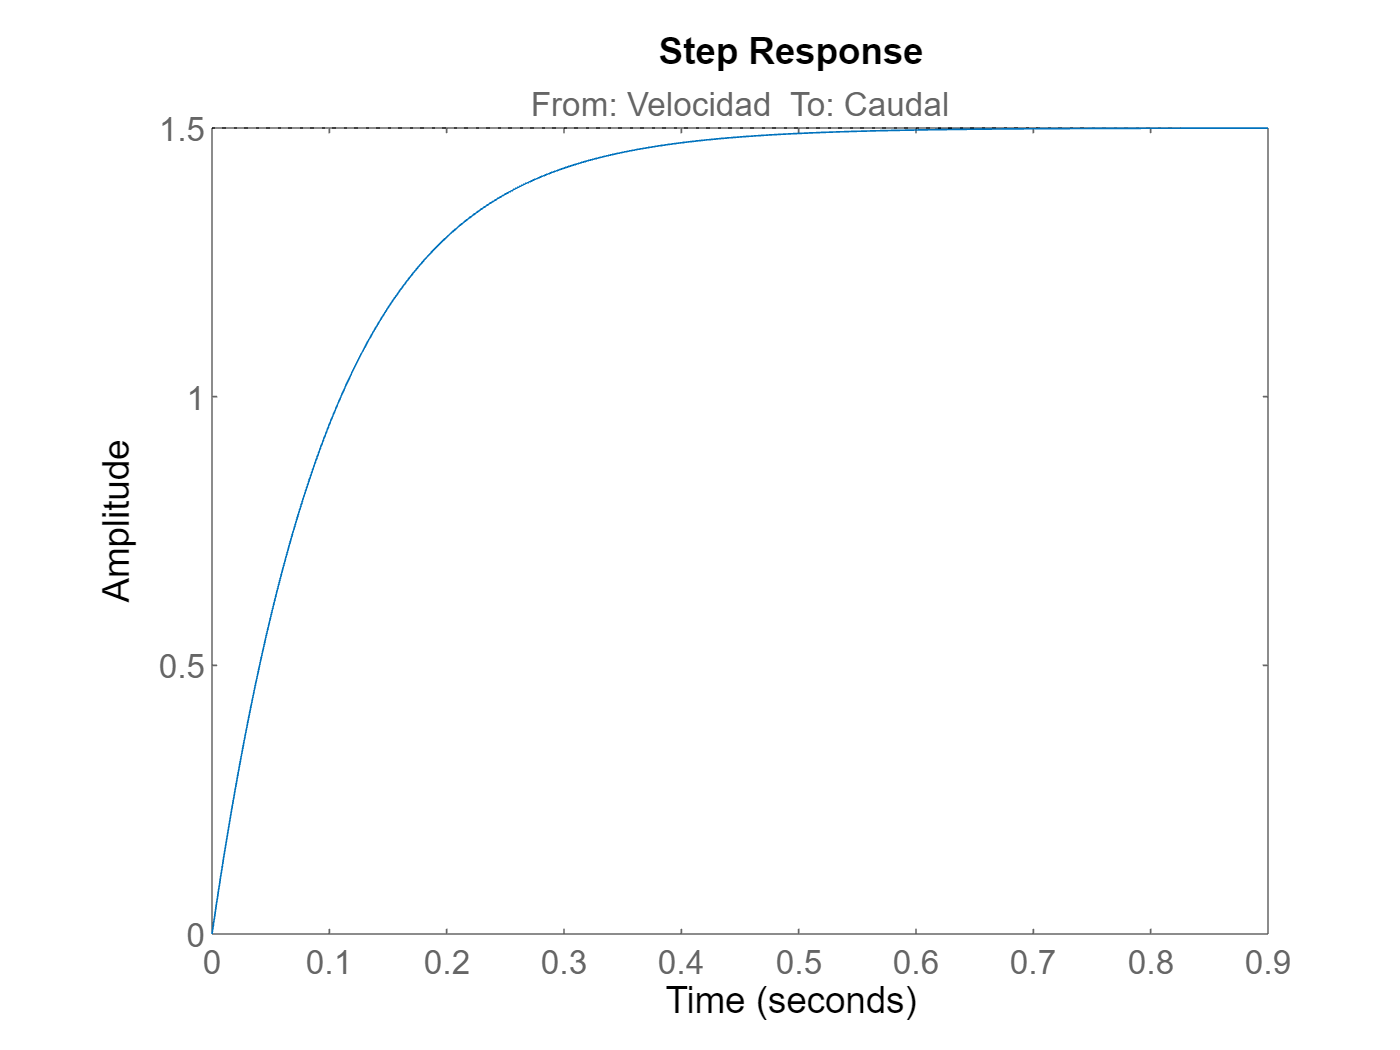

sys_syr = tf(1.5,[0.1 1],...
    'InputName','Velocidad',...
    'InputUnit','cm per min',...
    'OutputName','Caudal',...
    'OutputUnit','ml per min');
step(sys_syr)

### Subsistema electromecánico (actuador)

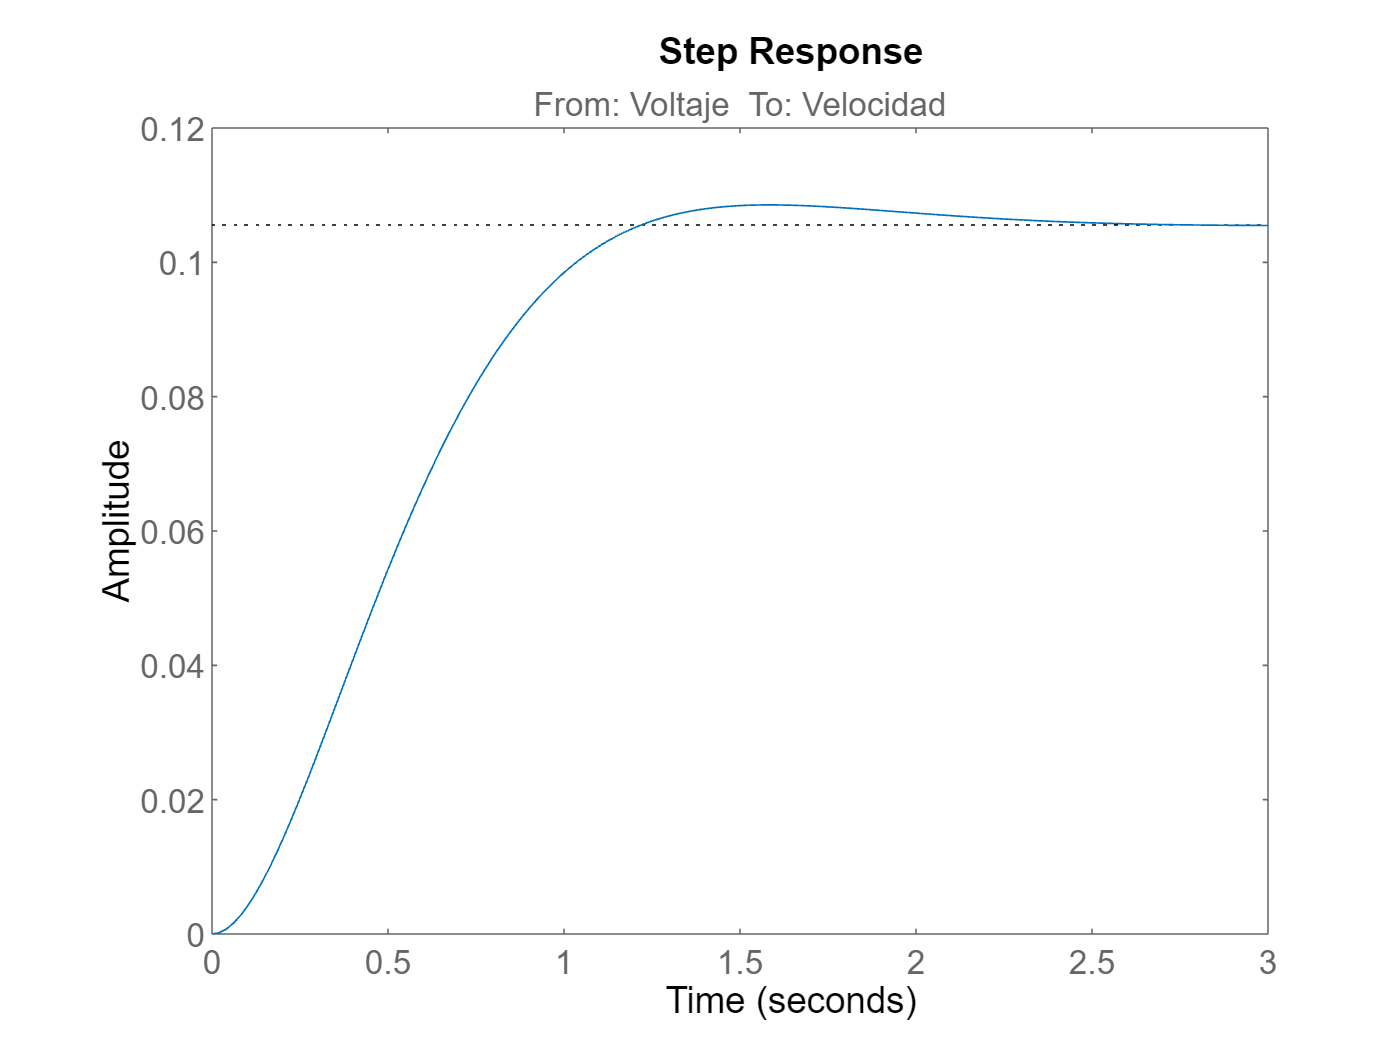

sys_elec = tf(0.95,[1 2*0.75*3 3^2],...
    'InputName','Voltaje',...
    'InputUnit','mV',...
    'OutputName','Velocidad',...
    'OutputUnit','cm per min');
step(sys_elec)

### Sistema completo en lazo abierto

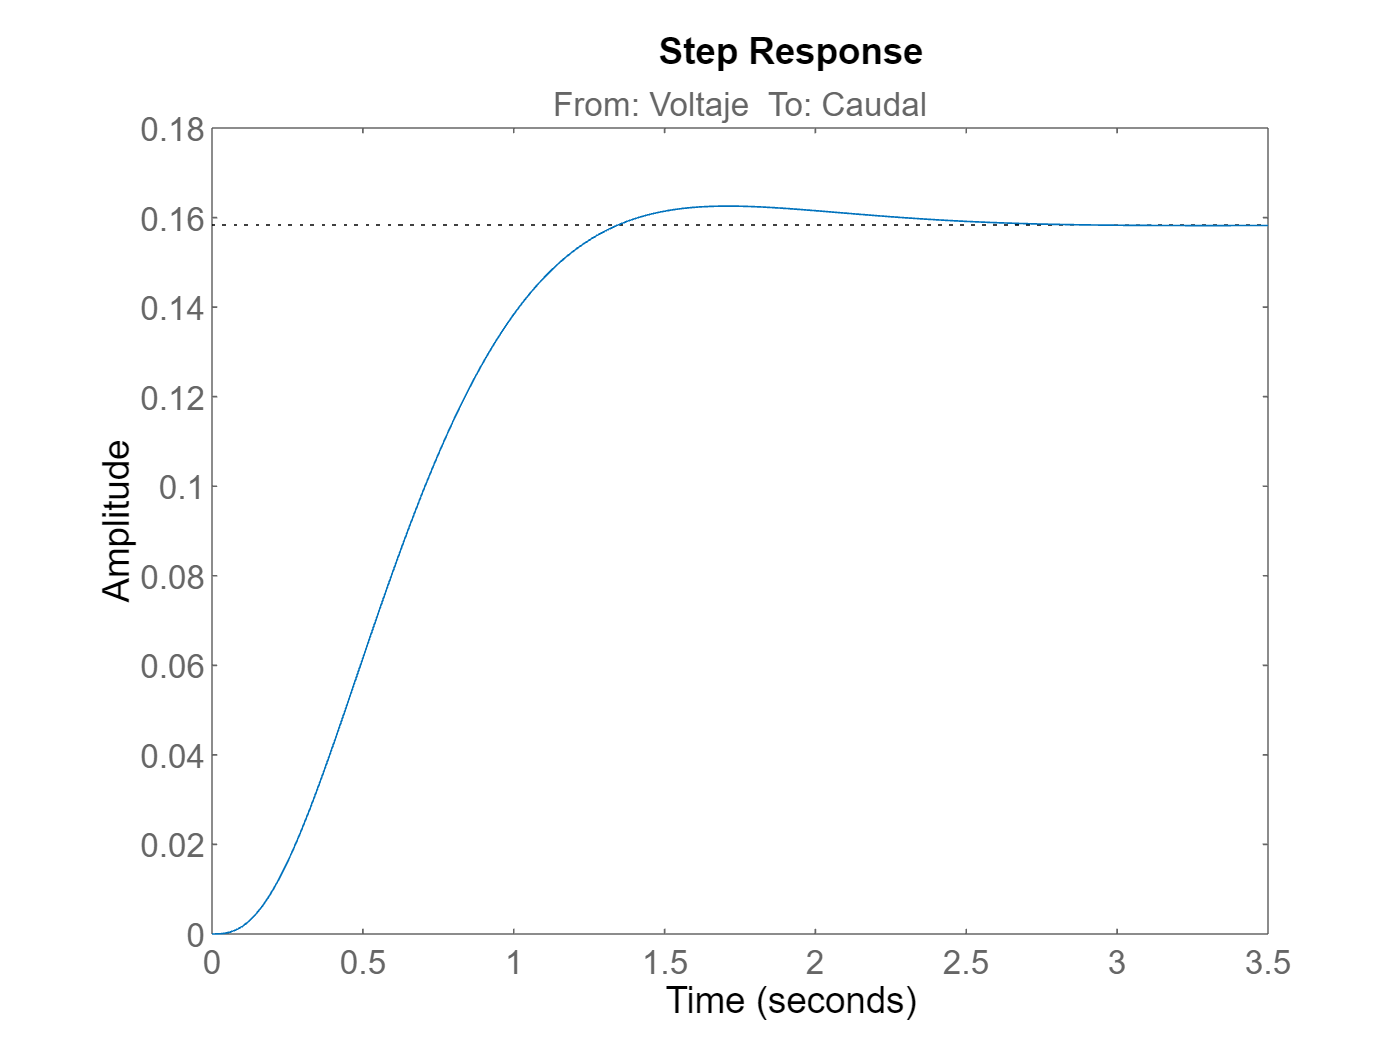

sys_pump = series(sys_elec,sys_syr);
step(sys_pump)

### Adición de ganancia en lazo abierto

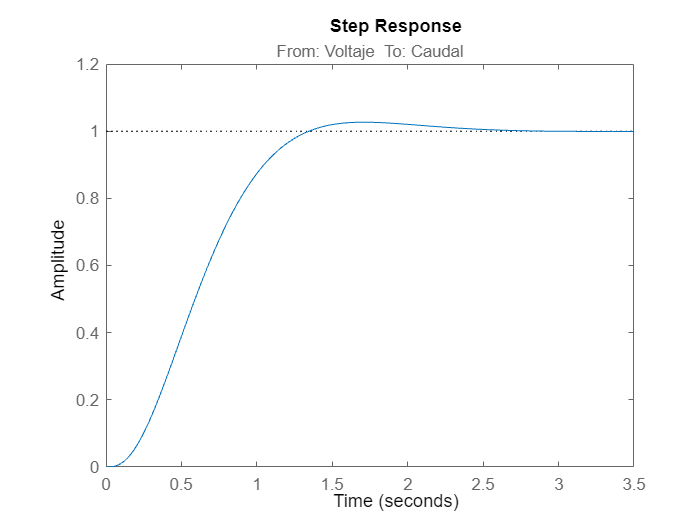

sys_pump_k = 9*sys_pump/1.425;
sys_pump_k.InputName = 'Voltaje';
sys_pump_k.OutputName = 'Caudal';
step(sys_pump_k)

## Efectos de la realimentación

### Respuesta en lazo abierto

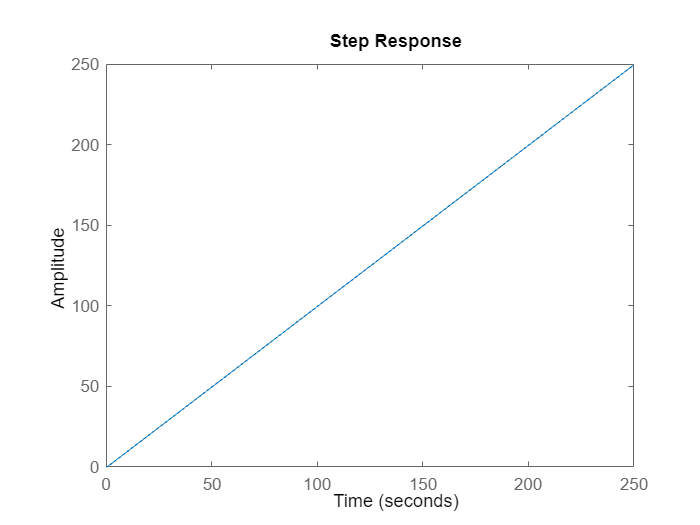

sys_ol = tf(2,[1 2 0]);
step(sys_ol)

### Respuesta lazo cerrado (Realimentación unitaria)

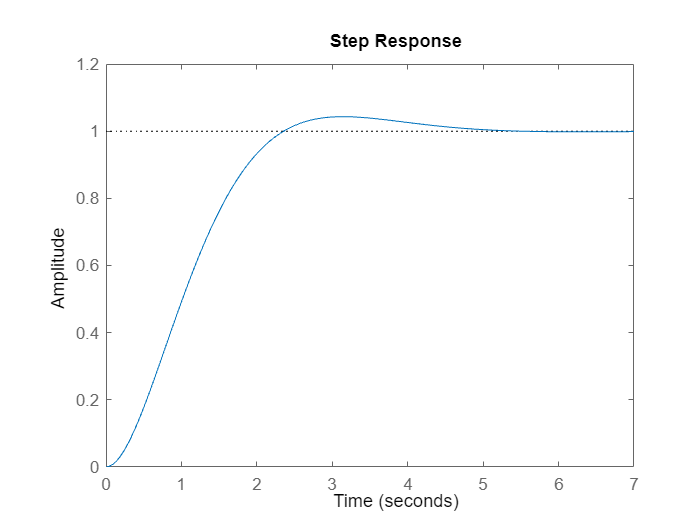

sys_cl = feedback(sys_ol,1);
step(sys_cl)

### Respuesta lazo cerrado (Sensor en el lazo de realimentación)

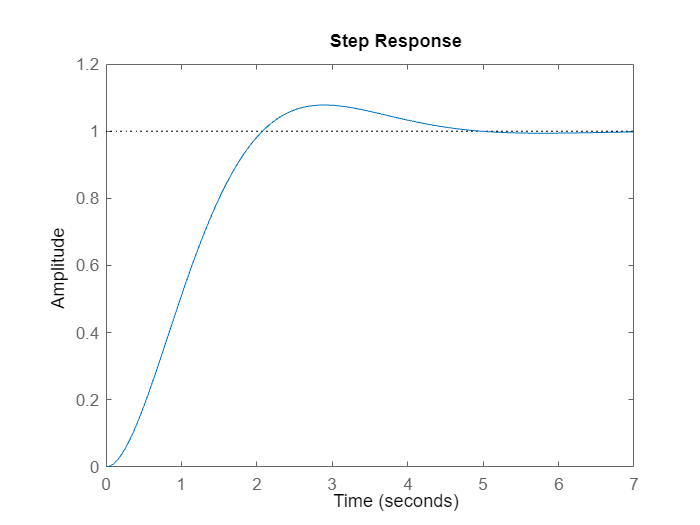

sys_sens = tf(1,[.1 1]);
sys_cl = feedback(sys_ol,sys_sens);
step(sys_cl)